# CONDITIONAL ANALYSIS:

#  Differences in the DV among nodes with high IV during BASELINE, VS among nodes with high IV DURING CONTROL

# DONE

## First retreive Master Data Set

cog_task_list = {'PVT'};
df_long =  dflong('cogtestlist',cog_task_list,'getd2cdf',false);

## INITIATE

clearvars -except df_long; clc;


% SETTINGS
cogtask = 'PVT';
bandname  = 'delta';
IV = 'deg_w'; 
DV = 'gpsd'; 
numlevels = 3;
t=1;
bonfcorrect = 2;
categwthn_condition = true;
categwthn_subject = true;
condition2analyze = "control";
run_sbj_test = true;
% INIT
DV_mean =  sprintf('mean_%s',DV);
IV_level  = sprintf('%s_level',IV);
desired_vars = [{DV},{IV},experimentalvars()];

% LOAD DATA
df     = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t,'keepchannels',true);
df = df(:,desired_vars);

% PROCESS MORE
df= categcolumn(df,IV,numlevels,"condition",categwthn_condition,"subject",categwthn_subject);
df.(IV_level) = findgroups(df.(IV_level));
[df_bsl, df_ctr, df_lgt] = splitdfbycondition(df);
df = dfrmcats(df);
df_hgh = df(df.(IV_level)==numlevels & (df.condition == "baseline" | df.condition ==condition2analyze),:);
df_low = df(df.(IV_level)==1 & (df.condition == "baseline" | df.condition ==condition2analyze),:);


% SUBJECT IDS
sbjid_list = unique(df.sbj);
numsubj = numel(sbjid_list);
example_subject = sbjid_list(1);

% FUNCTIONS
getrows         = @(df_sbj_ctr, ch_IV_low_bsl) ismember(df_sbj_ctr.chan, ch_IV_low_bsl);
getDV           = @(df,desired_chan) df.(DV)(getrows(df, desired_chan));


INIT FIGURES


clc;
close all;
figure('GraphicsSmoothing','off','Visible','on');
T = tiledlayout(4,3)

T =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties

T.Title.String = sprintf(' [%s %s] after waking (%s @t=%d)\namong nodes with high levels of %s during *baseline*, vs those with High %s during *control/light*', bandname, upper(DV), cogtask, t,upper(IV), upper(IV))

T =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties

T.Title.Interpreter = "none";
T.Title.FontWeight = "bold";

# -------------ANALYSIS:1.1 ----------------------- 

% ANALYSIS:1.1 For each subject, get Differences in DV among nodes with high
% IV during their respective conditions, 

% PLOT BOXES
plotsbjbox = @(df_loworhigh) boxchart(df_loworhigh.sbj,df_loworhigh.(DV),'GroupByColor',df_loworhigh.condition);

ax_box_high = nexttile(1,[1 3]);
hold on;
plotsbjbox(df_hgh);
legend

ax_box_low = nexttile(4,[1 3]);
hold on;
plotsbjbox(df_low);


getsbjdv = @(iv_level,condition,subject) df.(DV)(df.condition == condition & df.(IV_level) == iv_level &  df.sbj == subject)    

getsbjdv = function_handle with value:
    @(iv_level,condition,subject)df.(DV)(df.condition==condition&df.(IV_level)==iv_level&df.sbj==subject)


for j = 1:numsubj
    sbjid = sbjid_list(j);

    Y_bsl = getsbjdv(numlevels,'baseline',sbjid);
    Y_ctr = getsbjdv(numlevels,'control',sbjid);

    if run_sbj_test
        p = ranksum(Y_bsl,Y_ctr);
        axes(ax_box_high);
        h = sigstar({[sbjid-.3 sbjid+.3]});
        fixsigstar(h,p,1)
    end

    Y_bsl = getsbjdv(1,'baseline',sbjid);
    Y_ctr = getsbjdv(1,'control',sbjid);

    if run_sbj_test
        axes(ax_box_low)        ;
        p = ranksum(Y_bsl,Y_ctr);
        h = sigstar({[sbjid-.3 sbjid+.3]});
        fixsigstar(h,p,1)
    end

end
ylabel(ax_box_high,sprintf('%s %s\n for nodes with HIGH %s',bandname,upper(DV),upper(IV)),'Interpreter','none')
legend(ax_box_high, {sprintf('Channels w/"HIGH" %s *DURING BASELINE*',upper(IV)), sprintf('w/"HIGH" %s DURING CONTROL',upper(IV)),'rankSUM(independent)'},'Location','best','Interpreter','none','FontSize',6);

ylabel(ax_box_low,sprintf(' %s\n for nodes with LOW %s',upper(DV),upper(IV)),'Interpreter','none')
legend(ax_box_low, {sprintf('Channels w/"LOW" %s *DURING BASELINE*',upper(IV)), sprintf('w/"LOW" %s DURING CONTROL',upper(IV)),'rankSUM(independent)'},'Location','best','Interpreter','none','FontSize',6);
xlabel('Subject ID')


# ANALYSIS 

% Differences in DV among nodes with high IV during baseline, VS among
% nodes with high IV during control. first analysis i did, which was a bit
% hard to interpret: notoe that this does not tell us if the high IV nodes
% during baseline are the ones that changed in the DV. 
%
% NO AVERAGING the DV of nodes within a subject:
% 
% WE USE RANK SUM BECAUSE SAMPLES ARE NOT PAIRED (EG HIGH LEVEL
% NODES COULD BE DIFFERENT IN ONE CONDITION and they look non-normal)

df_mean = groupsummary(df,{'chan',IV_level,'condition','sbj'},'mean',DV);
df_mean = df_mean(ismember(df_mean.(IV_level),[1,numlevels]),:);

getdfdv = @(df_mean,dv,condition,ivlevel) df_mean.(dv)(df_mean.condition == condition & df_mean.(IV_level) == ivlevel);


% COMPARE NODES WITH LOW LEVELS OF THE IV
% compare lower 3rd of channesls  of all subjects between baseline and
% control : about (~8) * numsubjects data points per group

% PLOT BOX CHART 
nexttile
boxchart(df_mean.(IV_level),df_mean.(DV_mean), 'GroupByColor',df_mean.condition)
xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))



    % COMPARE NODES WITH LOW LEVELS OF THE IV
    xbsl_min = getdfdv(df_mean,DV_mean,'baseline',1);
    xctr_min = getdfdv(df_mean,DV_mean,'control',1);
    xlgt_min = getdfdv(df_mean,DV_mean,'light',1);
    
    p = ranksum(xbsl_min,xctr_min);
    h = sigstar({[1-.33 1]});
    fixsigstar(h,p,2)
    
    p = ranksum(xbsl_min,xlgt_min);
    h = sigstar({[1-.33 1.33]});
    fixsigstar(h,p,2)
    
    % COMPARE NODES WITH HIGH LEVELS OF THE IV
    xbsl_max = getdfdv(df_mean,DV_mean,'baseline',numlevels);
    xctr_max = getdfdv(df_mean,DV_mean,'control',numlevels);
    xlgt_max = getdfdv(df_mean,DV_mean,'light',numlevels);
    
    p = ranksum(xbsl_max,xctr_max);
    h = sigstar({[numlevels-.33 numlevels]});
    fixsigstar(h,p,2)
    
    p = ranksum(xbsl_max,xlgt_max);
    h = sigstar({[numlevels-.33 numlevels+.33]});
    fixsigstar(h,p,2)
    

ylabel(sprintf('%s %s',bandname, DV))
legend({'BSLN','CTRL','LGHT','rankSIGN(independent)'},'Location','best','FontSize',8)


% PLOT HISTOGRAM COMPARING THE DV OF LOW IV NODES
nexttile;
hold on;
histogram(xbsl_min,15,'FaceColor','k');
histogram(xctr_min,15);
xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))
legend({'Channels during baseline','during control'})
title(sprintf('%s of channels with **LOW** LEVELS OF %s',upper(DV), upper(IV)))
ylabel(sprintf('%s %s',bandname, DV))

% PLOT HISTOGRAM COMPARING THE DV OF HIGH IV NODES
nexttile;
hold on;
histogram(xbsl_max,15,'FaceColor','k');
histogram(xctr_max,15);
xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))
legend({'Channels during baseline','during control'})
title(sprintf('%s of channels with **HIGH** LEVELS OF %s',upper(DV), upper(IV)))
ylabel(sprintf('%s %s',bandname, DV))


# ANALYSIS:3

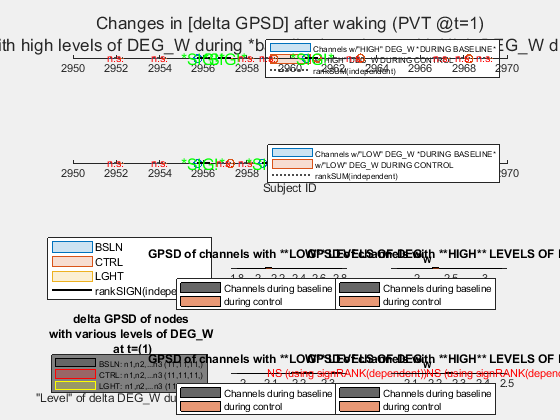


% ------------------------------------ 
% ANALYSIS 
% 
% Differences in DV among nodes with high IV during baseline, VS among
% nodes with high IV during control. We do 


% FIRST
% BOX PLOT

anzcond_box(df,DV,IV,IV_level,'signrank');

% PLOT HISTOGRAM COMPARING THE DV OF LOW IV NODES
df_bsl_mean = groupsummary(df_bsl,{'condition',IV_level,'sbj'},'mean',DV);
df_ctr_mean = groupsummary(df_ctr,{'condition',IV_level,'sbj'},'mean',DV);


df_bsl_iv_lev_min = df_bsl_mean.(DV_mean)(df_bsl_mean.(IV_level) == 1,:);
df_ctr_iv_lev_min = df_ctr_mean.(DV_mean)(df_ctr_mean.(IV_level) == 1,:);
p = signrank(df_bsl_iv_lev_min,df_ctr_iv_lev_min);


nexttile;
hold on;
histogram(df_bsl_iv_lev_min,10,'FaceColor','k');
histogram(df_ctr_iv_lev_min,10);

if p<.05/2
    text(.3,.8,'Significant using signRANK','Color','g','FontSize',12,'Units','normalized')
else
    text(.3,.9,'NS (using signRANK(dependent))','Color','r','FontSize',8,'Units','normalized')
end


xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))
legend({'Channels during baseline','during control'})
title(sprintf('%s of channels with **LOW** LEVELS OF %s',upper(DV), upper(IV)))
ylabel(sprintf('%s %s',bandname, DV))

drawnow

% PLOT HISTOGRAM COMPARING THE DV OF HIGH IV NODES

df_bsl_iv_lev_max = df_bsl_mean.(DV_mean)(df_bsl_mean.(IV_level) == numlevels,:);
df_ctr_iv_lev_max = df_ctr_mean.(DV_mean)(df_ctr_mean.(IV_level) == numlevels,:);

p = signrank(df_bsl_iv_lev_max,df_ctr_iv_lev_max);

nexttile;
hold on;
histogram(df_bsl_iv_lev_max,10,'FaceColor','k');
histogram(df_ctr_iv_lev_max,10);


if p<.05/2
    text(.3,.8,'Significant using rank sign','Color','g','FontSize',12,'Units','normalized')
else
    text(.3,.9,'NS (using signRANK(dependent))','Color','r','FontSize',8,'Units','normalized')
end
xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))
legend({'Channels during baseline','during control'})
ylabel(sprintf('%s %s',bandname, DV))
title(sprintf('%s of channels with **HIGH** LEVELS OF %s',upper(DV), upper(IV)))

# FUNCTIONS

function ax=anzcond_box(df,DV,IV,IV_level,testtype, opts)
    arguments
        df
        DV
        IV
        IV_level
        testtype
        opts.bonfcorrect = 2
        opts.anzexample = [];
    end
    
    numlevels = numel(unique(df.(IV_level)));

    % GET THE AVERAGE VALUE OF THE DV, GROUP BY FOR EACH LEVEL OF THE IV
    % FOR A GIVEN SUBJECT IN A PARTICULAR CONDITION
    df_mean_ch = groupsummary(df, ["condition", IV_level,"sbj","chan"],{"mean"},{DV});

    df_mean = groupsummary(df, ["condition", IV_level,"sbj"],{"mean"},{DV});
    DV_mean =  sprintf('mean_%s',DV);
    
    % TEST
    sig_pairs_lev_mean = {};
    
    for level = 1:numlevels
        df_mean_lev = df_mean(df_mean.(IV_level) == level,:);
        [~,~,tests(level)] = runmultitests(df_mean_lev,DV_mean,'printSummResults',false,'printAllResults',false);
        sig_pairs_lev_mean = cat(2,getsigpairs(tests(level), level,'testtype',testtype,'bonfcorrect',opts.bonfcorrect),sig_pairs_lev_mean);
    end
    
    
    % PLOT  
    % BOX PLOTS OF THE MEANS OF SUBJECTS
    df_mean.(DV_mean) = df_mean.(DV_mean);
    df_mean.(IV_level) = findgroups(df_mean.(IV_level));
    
    ax = nexttile; hold on
    ax.Color = [.5 .5 .5];
    ax_bx = boxchart(df_mean.(IV_level),df_mean.(DV_mean),'GroupByColor',df_mean.condition,'Notch','off');
    ax_bx(1).BoxFaceColor = 'k';
    ax_bx(2).BoxFaceColor = 'r';
    ax_bx(3).BoxFaceColor = 'y';
    
    ax_bx(1).YData(~ismember(ax_bx(1).XData,[1 numlevels])) = nan;    
    ax_bx(2).YData(~ismember(ax_bx(2).XData,[1 numlevels])) = nan;    
    ax_bx(3).YData(~ismember(ax_bx(3).XData,[1 numlevels])) = nan;    
    
    
    % SHOW SPECIFIC DATA POINTS FROM EACH SUBJECT
    markkeroffset = [-.33 0 .33];
    condition_list = {'baseline','control','light'};
    color_list = ["k","r","y"];
    
    for i = 1:3
        df_cnd= df_mean(df_mean.condition == condition_list(i),:);
        df_cnd.(IV_level) = findgroups(df_cnd.(IV_level));
        x =  df_cnd.(IV_level)+ markkeroffset(i); 
        y = df_cnd.(DV_mean);
        ax_scatt = scatter(x,y,color_list(i),'filled','MarkerEdgeColor','k'); 
        
        ax_scatt.YData(~ismember(df_cnd.(IV_level),[1 numlevels])) = nan;    
    end
    
    sigstar(sig_pairs_lev_mean);

    % GET INFORMATION OF THE ANALYSIS
    % error will occur if df has more than one band, time point or task.
    % this is good
    bandname = unique(df.band_ord);
    t = unique(df.run(df.run~=0));
    cogtask = unique(df.cogtest);


    bl_str = strcat( sprintf('BSLN: n1,n2,...n%d (',numlevels), sprintf('%d,', groupcounts(ax_bx(1).XData)) ,')');
    ctrl_str = strcat( sprintf('CTRL: n1,n2,...n%d (',numlevels), sprintf('%d,', groupcounts(ax_bx(2).XData)) ,')');
    light_str = strcat( sprintf('LGHT: n1,n2,...n%d (',numlevels), sprintf('%d,', groupcounts(ax_bx(3).XData)) ,')');
    
   

    % PLOT INFO ON LABELS AND LEGENDS
    ylabel(sprintf('%s %s %s',bandname, upper(DV), cogtask),'Interpreter','none')
    xlabel(sprintf('"Level" of %s %s during %s ',bandname, upper(IV),lower(cogtask)),'Interpreter','none')
    title(sprintf('%s %s of nodes\nwith various levels of %s\n at t=(%s)\n during %s',upper(bandname), ...
        upper(DV), upper(IV),num2str(t),cogtask),'Interpreter','none');
    
    if ~isempty(sig_pairs_lev_mean)
        legend({bl_str,ctrl_str,light_str,sprintf('%s test',testtype)},'Location','best','Interpreter','none','FontSize',6);
    else
        legend({bl_str,ctrl_str,light_str},'Location','best','Interpreter','none','FontSize',6);
    end
    

end

function [lm,ax_lm] =  anzcond_scatt(df_condition, DV,IV,IV_level,opts)
    arguments
        df_condition
        DV
        IV
        IV_level
        opts.anzexample = [];
    end    
    low_level_rows =  df_condition.(IV_level) == 1;
    hgh_level_rows =  df_condition.(IV_level) == max(df_condition.(IV_level));
    mid_level_rows = ~low_level_rows & ~hgh_level_rows;
    
    % fit model
    lm = fitlm(df_condition,"linear","ResponseVar",(DV),"PredictorVars",(IV));
        
    % Plot 
    
    % PLOT LINEAR MODEL
    ax_lm = lm.plot;
    hold on;
    delete(ax_lm([1 3 4]))
    set(ax_lm(2),'LineStyle', '-','Color','k')
    
    % SCATTER PLOT FOR HIGH AND LOW LVELS
    scatter(df_condition(mid_level_rows,:),IV,DV,'MarkerEdgeColor',[.3 .3 .3],'SizeData',10);
    scatter(df_condition(low_level_rows,:),IV,DV,'filled','MarkerFaceColor','b','MarkerEdgeColor','none','SizeData',10);
    scatter(df_condition(hgh_level_rows,:),IV,DV,'filled','MarkerFaceColor','m','MarkerEdgeColor','none','SizeData',10);

    
    % SAME FOR 
    if ~isempty(opts.anzexample)
        eg_sbj_rows=  df_condition.sbj == opts.anzexample;

        
        lm_egsbj = fitlm(df_condition(eg_sbj_rows,:),"linear","ResponseVar",(DV),"PredictorVars",(IV));
        ax_lm_egsbj = lm_egsbj.plot;
        delete(ax_lm_egsbj([1 3 4]))
        set(ax_lm_egsbj(2),'LineStyle', '-','Color','w') 

        scatter(df_condition(low_level_rows & eg_sbj_rows,:),IV,DV,'MarkerFaceColor','b','MarkerEdgeColor','w','Marker','diamond','SizeData',100);    
        scatter(df_condition(hgh_level_rows & eg_sbj_rows,:),IV,DV,'MarkerFaceColor','m','MarkerEdgeColor','w','Marker','diamond','SizeData',100);
    end
end

function fixsigstar(h,p,bonfcorrect)

    if p<.05/(bonfcorrect)
            set(h(2),'String','*SIG!*')
            set(h(2),'Color','g',"FontSize",12)    
        else
            set(h(2),'String','n.s.')
            set(h(2),'Color','r',"FontSize",8)    
            set(h(1),'LineStyle',':','Color',[.3 .3 .3])        
    end
end